# prepare the data


%the stupid narxnet only takes cell array as input, 

未定义变量 kchousedata。

% it crush all the x features into a cell! how stupid and inconsitent
xs_train=exp8{1:6:end-1000,3:5}
ys_train=exp8{1:6:end-1000,2}

xs_train=tonndata(xs_train,false,false)
ys_train=tonndata(ys_train,false,false)


% the first 24 of the test is not the test it is know data
% prediction start from 25
xs_test=exp8{end-1144:6:end,3:5}
ys_test=exp8{end-1144:6:end,2}

xs_test=tonndata(xs_test,false,false)
ys_test=tonndata(ys_test,false,false)


## make the net and train it


% make the nn with 24 delay and 10 hiden units
net3 = narxnet(1:24,1:24,10);
% very stupid that you need to prepare the data using the net then feed it
% with this data, it can pre-process the data anyway.
[Xs,Xi,Ai,Ts] = preparets(net3,xs_train,{},ys_train);

net3 = train(net3,Xs,Ts,Xi,Ai);

## predict


% make it closse loop so we can predict multiple steps into the future
net4 = closeloop(net3)


net4 =

    Neural Network
 
              name: 'NARX Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 24
    numLayerDelays: 24
 numFeedbackDelays: 24
 numWeightElements: 981
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inputConnec


% you have to init the nn with at least 24 (delays) 
[Xs,Xi,Ai,Ts] = preparets(net4,xs_test(1:24),{},ys_test(1:24));

% feed it wiht the new data and the init state
yhat = net4(xs_test(25:end),Xi,Ai);


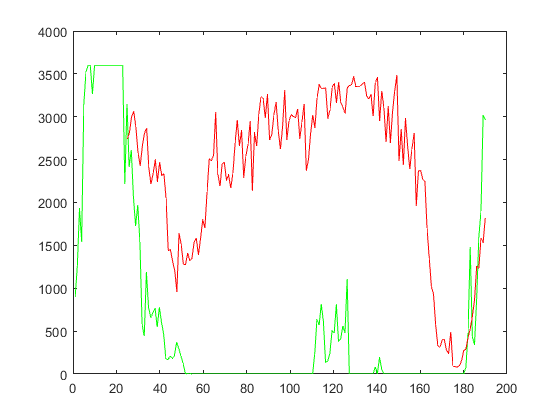

%plot the result, the result is like shit.
hold off
plot(linspace(1,190,191),cell2mat(ys_test),"g")
hold on
plot(linspace(25,190,167),cell2mat(yhat),"r")

## Bottom line: one must be out of his/her fucking mind to use matlab nn! Fuck!